## Display the original image on screen.

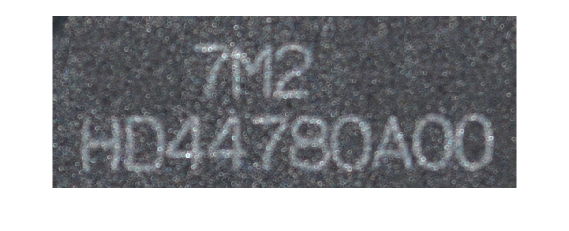

clc; clear;
img = imread('charact2.bmp');
imshow(img);

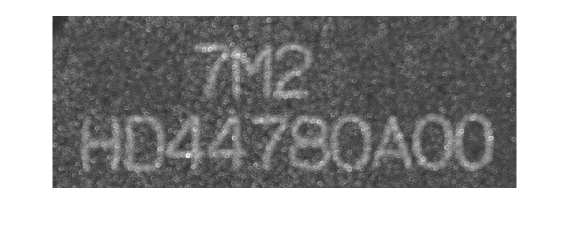

% Convert the Image to Grayscale
grayImg = rgb2gray(img);
imshow(grayImg);

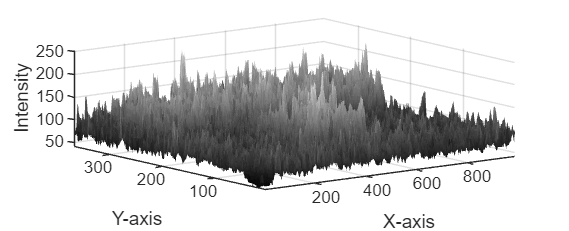

% Create a 3D plot of the grayscale image
create3DIntensityPlot(grayImg);

## Implementing a 3x3 Averaging Mask

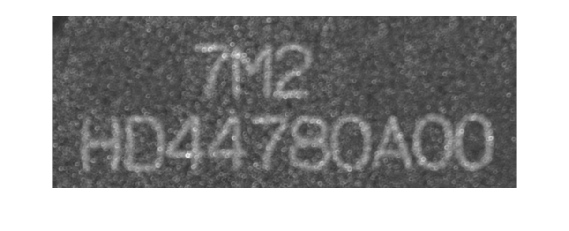

% Create a 3x3 averaging filter
avgFilter = ones(3, 3) / 9;
% Apply the averaging filter to the image
avgFilteredImg = imfilter(grayImg, avgFilter);
% Show the avg filter image
imshow(avgFilteredImg);

## Implementing a 3x3 Rotating Mask

filteredImg = rotmask(grayImg, 'vectorized', 'double');

 100.00 % 


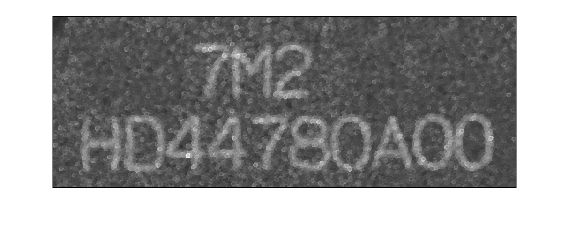

imshow(filteredImg);

## Gaussian Filtering

% gaussFilteredImg = imgaussfilt(grayImg, 2);
% imshow(gaussFilteredImg);
% create3DIntensityPlot(gaussFilteredImg);

## Sobel operation

% SobelMagnitude = applySobel(gaussFilteredImg);
% imshow(SobelMagnitude);
% create3DIntensityPlot(SobelMagnitude);

## Experiment with masks of different sizes

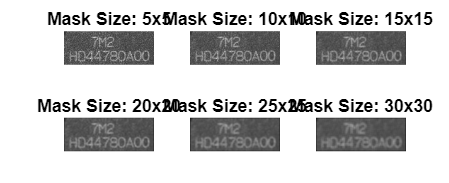

% AvgFiltering
% Loop through different mask sizes
for k = 5:5:30
    % Create an averaging mask of size k x k
    avgFilter = ones(k, k) / (k*k);
    % Apply the averaging filter to the image
    avgFilteredImgEx = imfilter(grayImg, avgFilter);
    % Show the avg filter image
    subplot(2, 3, k/5); % Adjust the subplot position as needed
    imshow(avgFilteredImgEx);
    title(['Mask Size: ' num2str(k) 'x' num2str(k)]);
end

clf;

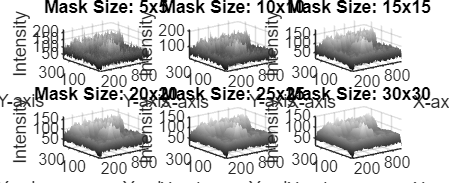

for k = 5:5:30
    % Create an averaging mask of size k x k
    avgFilter = ones(k, k) / (k*k);
    % Apply the averaging filter to the image
    avgFilteredImgEx = imfilter(grayImg, avgFilter);
    % Show the avg filter image
    subplot(2, 3, k/5); % Adjust the subplot position as needed
    create3DIntensityPlot(avgFilteredImgEx);
    title(['Mask Size: ' num2str(k) 'x' num2str(k)]);
end

clf;

## Morphological Operation

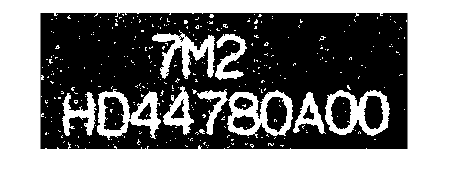

% Process the image to extract "HD44780A00", find outlines and segment characters
thresholdValue = graythresh(avgFilteredImg);
binaryImg = imbinarize(avgFilteredImg, thresholdValue);
imshow(binaryImg);

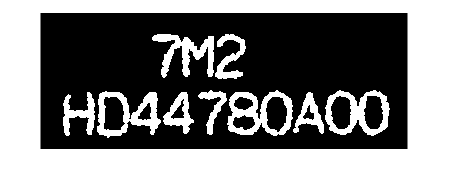

morphProcessedImg = applyMorphologicalProcessing(binaryImg);
imshow(morphProcessedImg);

## Extract Sub-Image

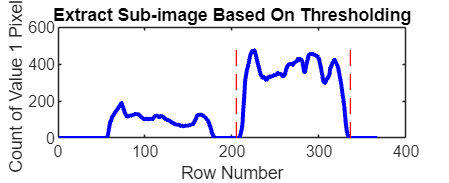

% extract sub-image
counts = sum(morphProcessedImg, 2);
threshold = 250;
startOfCharacters = find(counts > threshold, 1, 'first') - 10;
endOfCharacters = find(counts > threshold, 1, 'last') + 10;
plot(counts, 'b', 'LineWidth', 2);
title('Extract Sub-image Based On Thresholding');
xlabel('Row Number');
ylabel('Count of Value 1 Pixels');
ylim = get(gca, 'YLim'); % Get the current y-axis limits
line([startOfCharacters startOfCharacters], ylim, 'Color', 'r', 'LineStyle', '--');
line([endOfCharacters endOfCharacters], ylim, 'Color', 'r', 'LineStyle', '--');

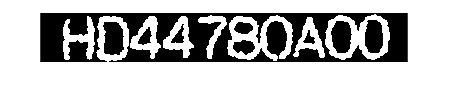

lowerImg = morphProcessedImg(startOfCharacters:endOfCharacters, :);
imshow(lowerImg);

## Find edges and segment characters

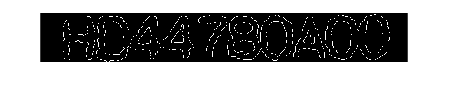

% Find edges and segment characters
charEdges = edge(lowerImg, 'canny'); % Detect edges
imshow(charEdges);

[charLabels, ~] = bwlabel(lowerImg) % Label connected components

charLabels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

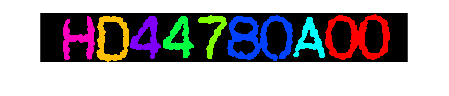

coloredLabels = label2rgb(charLabels, 'hsv', 'k', 'shuffle'); % Color labels for visualization
imshow(coloredLabels);

## Segment Characters

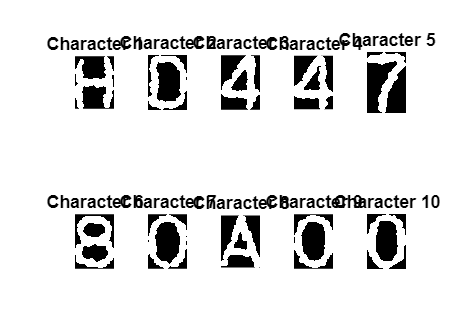

% Define the directory to save character images
outputDir = 'Characters';  % Change this to your desired path
if ~exist(outputDir, 'dir')
    mkdir(outputDir);  % If the directory doesn't exist, create it
end

% Segment characters
% Label connected components
[charLabels, charNum] = bwlabel(lowerImg);

% Calculate the number of rows and columns for the subplot grid
numRows = 2;
numCols = 5;

% Create a single subplot for all character images
figure;

charIdx = 1;
for n = 1:charNum
    % Find the boundaries of the nth character
    [row, col] = find(charLabels == n);
    
    % Determine the bounding box around the character
    topRow = min(row);
    bottomRow = max(row);
    leftColumn = min(col);
    rightColumn = max(col);
    
    % Cut the character out of the image
    characterImg = lowerImg(topRow:bottomRow, leftColumn:rightColumn);

    if (n == 6) || (n == 8)
        [height, width] = size(characterImg);
        midPoint = round(width / 2);
        % Crop the left and right halves
        leftHalf = characterImg(:, 1:midPoint);
        rightHalf = characterImg(:, midPoint+1:end);
        subplot(numRows, numCols, charIdx);
        imshow(leftHalf);
        title(['Character ', num2str(charIdx)]);
        imwrite(leftHalf, fullfile(outputDir, sprintf('Character_%02d.png', charIdx)));
        charIdx = charIdx + 1;
        subplot(numRows, numCols, charIdx);
        imshow(rightHalf);
        title(['Character ', num2str(charIdx)]);
        imwrite(rightHalf, fullfile(outputDir, sprintf('Character_%02d.png', charIdx)));
        charIdx = charIdx + 1;
        continue;
    end
    
    % Display each character in the subplot
    subplot(numRows, numCols, charIdx);
    imshow(characterImg);
    title(['Character ', num2str(charIdx)]);
    
    % Save the character image as a PNG file in the output directory
    imwrite(characterImg, fullfile(outputDir, sprintf('Character_%02d.png', charIdx)));
    
    charIdx = charIdx + 1;
end

clf;

## Functions

### create3DIntensityPlot

function create3DIntensityPlot(img)
    % Check if the image is grayscale; if not, convert it
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    % Create a 3D plot of the grayscale image
    [X, Y] = meshgrid(1:size(img, 2), 1:size(img, 1));
    Z = double(img);
    surf(X, Y, Z, 'EdgeColor', 'none');
    % colormap('gray'), axis tight, view(-35, 45);
    colormap('gray'), axis tight;
    xlabel('X-axis'), ylabel('Y-axis'), zlabel('Intensity');
    % title('3D Intensity Plot of Image');
end

### sobel operation

function sobelMagnitude = applySobel(img)
    % Sobel filter for horizontal and vertical edge detection
    Gx = [-1 0 1; -2 0 2; -1 0 1];
    Gy = [-1 -2 -1; 0 0 0; 1 2 1];
    % Apply the horizontal Sobel filters
    grad_x = imfilter(double(img), Gx, 'same', 'replicate');
    % Apply the vertical Sobel filters
    grad_y = imfilter(double(img), Gy, 'same', 'replicate');
    % Display both gradients
    % subplot(1, 2, 1), imshow(grad_x), title('Horizontal Edges (Sobel - Gx)');
    % subplot(1, 2, 2), imshow(grad_y), title('Vertical Edges (Sobel - Gy)');
    % Calculate the magnitude of the gradient
    sobelMagnitude = sqrt(grad_x.^2 + grad_y.^2);
    sobelMagnitude = mat2gray(sobelMagnitude);
end

### morphological operation

function morphProcessedImg = applyMorphologicalProcessing(binaryImg)
    % Create structuring element
    se = strel('disk', 5);
    binaryImg = imopen(binaryImg, se);
    binaryImg = bwareaopen(binaryImg, 200);
    morphProcessedImg = binaryImg;
end

function im_out = rotmask(im, method, datatype)
    if nargin<3    
      datatype = 'double';
    end    
    if nargin<2    
      method = 'vectorized';    
    end    
        
    imdatatype = class(im);    
        
    VECTORIZED = strcmp(lower(method), 'vectorized');    
    INTEGRAL = strcmp(lower(method), 'integral');    
    LOOP = strcmp(lower(method), 'loop');    
          
    if size(im,3)>1    
      error('rot_mask does not work for full-colour images')     
    end    
        
    mask_size = 9; % size of the rotating mask    
    mask=logical(zeros(5,5,mask_size));    
        
    im = double(im);      
    im_out = zeros(size(im));    
        
    if INTEGRAL     
    im_integral = feval( datatype, integralim(im) );    
    imsquare_integral = feval( datatype, integralim(im.^2) );    
      
    mask = zeros(2,4,9);    
    mask(:,:,1) = [-3 -3 0 0; -1 2 -1 2];    
    mask(:,:,2) = [-3 -3 0 0; -2 1 -2 1];    
    mask(:,:,3) = [-3 -3 0 0; -3 0 -3 0];    
    mask(:,:,4) = [-2 -2 1 1; -3 0 -3 0];    
    mask(:,:,5) = [-1 -1 2 2; -3 0 -3 0];    
    mask(:,:,6) = [-1 -1 2 2; -2 1 -2 1];    
    mask(:,:,7) = [-1 -1 2 2; -1 2 -1 2];    
    mask(:,:,8) = [-2 -2 1 1; -1 2 -1 2];    
    mask(:,:,9) = [-2 -2 1 1; -2 1 -2 1];    
        
    im_int_mat = zeros( 4,(size(im,1)-4)*(size(im,2)-4), 9,class(im_integral));    
    im_sq_mat  = zeros( 4,(size(im,1)-4)*(size(im,2)-4), 9,class(imsquare_integral));    
    row_pos = 3 : size(im,1)-2;    
    col_pos = 3 : size(im,2)-2;    
    for i = 1:9    
      for j = [1 4] % for each of the +corner     
        row_mask_pos = row_pos(1)+mask(1,j,i)+1 : row_pos(end)+mask(1,j,i)+1;    
        col_mask_pos = col_pos(1)+mask(2,j,i)+1 : col_pos(end)+mask(2,j,i)+1;    
        im_int_mat(j,:,i) = ...    
          reshape(im_integral(row_mask_pos,col_mask_pos),1,size(im_int_mat,2));    
        im_sq_mat(j,:,i)  = ...    
          reshape(imsquare_integral(row_mask_pos,col_mask_pos),1,size(im_sq_mat,2));    
      end    
      for j = [2 3]     
        row_mask_pos = row_pos(1)+mask(1,j,i)+1 : row_pos(end)+mask(1,j,i)+1;    
        col_mask_pos = col_pos(1)+mask(2,j,i)+1 : col_pos(end)+mask(2,j,i)+1;    
        im_int_mat(j,:,i) = ...    
         -reshape(im_integral(row_mask_pos,col_mask_pos),1,size(im_int_mat,2));    
        im_sq_mat(j,:,i)  = ...    
         -reshape(imsquare_integral(row_mask_pos,col_mask_pos),1,size(im_sq_mat,2));    
      end    
    end    
        
    sums = squeeze( sum(im_int_mat,1) )';    
    means = sums./mask_size;    
    sums_squares = squeeze( sum(im_sq_mat,1) )';    
    variances = mask_size*(means.^2) + sums_squares - 2*means.*sums;    
       
    [foo,idx_mins] = min(variances);    
      
    im_filt = means(sub2ind(size(means),idx_mins,[1:size(means,2)]));    
    im_filt = reshape( im_filt, length(row_mask_pos), length(col_mask_pos) );    
    im_out(3:end-2,3:end-2) = im_filt;    
    else % VECTORIZED and LOOP methods loop over (almost) all pixels in image    
    basic_shape = 1;    
      
    mask(1:3,3:5,1) = basic_shape;    
    mask(1:3,2:4,2) = basic_shape;    
    mask(2:4,2:4,9) = basic_shape;    
       
    for i = 3:8    
      mask(:,:,i) = rot90( mask(:,:,i-2) );    
    end    
      
    variances = zeros(1,9);    
    for i = 3:size(im,1)-2    
      for j = 3:size(im,2)-2    
        if VECTORIZED    
          sub_mat = im( i-2:i+2, j-2:j+2, ones(9,1) );     
          sub_mat = reshape( sub_mat(mask), mask_size, 9 );     
          means = sum(sub_mat)/mask_size;     
       
          variances = sum( (sub_mat-means(ones(mask_size,1),:)).^2 );    
          [min_disp,idx_min] = min(variances);       
          im_out(i,j) = means(idx_min);              
        elseif LOOP    
          sub_im = im( i-2:i+2, j-2:j+2 );    
          for m = 1:9   
            vec = sub_im( mask(:,:,m) );     
            variances(m) = sum( (vec-sum(vec)/mask_size).^2 );     
          end    
          [min_disp,idx_min] = min(variances);    
          im_out(i,j) = sum( sub_im(mask(:,:,idx_min)) ) / mask_size;    
        else    
          error('Unknown method');    
        end    
      end % for columns     
      fprintf( 1, '\b\b\b\b\b\b\b\b %05.2f %%', 100*(i-2)/(size(im,1)-2) );    
    end % for rows    
    fprintf(1,'\b\b\b\b\b\b\b\b %05.2f %% \n',100)    
    end % if INTEGRAL    
        
    if strcmp(imdatatype,'uint8')    
      im_out = uint8(round(im_out));    
    end    
    if strcmp(imdatatype,'uint16')    
      im_out = uint16(round(im_out));    
    end    
    if strcmp(imdatatype,'double') | strcmp(imdatatype,'single')    
      im_out = im_out/255;    
    end
end